close all;
clear all;
clc;

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints with 4 control points
waypoints = [-0.6, -0.4, 0.4, 0.7, 0.9, 0.8;  % X positions
             0.3, 0.9, 0.8, 0.4, 0.0, 0.3;  % Y positions
             0.0, 0.2, 0.4, 0.0, 0.2, 0.0]; % Z positions

% Transpose waypoints to match Catmull-Rom requirements
controlPoints = waypoints';

% Number of samples (interpolated points)
numSamples = 50;
interpolatedPoints = [];
velocities = [];
accelerations = [];

% Derive velocity and acceleration expressions for the spline
for i = 2:size(controlPoints, 1)-2
    P_prev = controlPoints(i-1, :);
    P_curr = controlPoints(i, :);
    P_next = controlPoints(i+1, :);
    P_next2 = controlPoints(i+2, :);
    
    for t = linspace(0, 1, numSamples / (size(controlPoints, 1)-3))
        % Position (P(t)) - already implemented in your spline code
        C_x = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(1) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(1) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(1) + ...
                     (t^3 - t^2) * P_next2(1));
                 
        C_y = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(2) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(2) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(2) + ...
                     (t^3 - t^2) * P_next2(2));
                 
        C_z = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(3) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(3) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(3) + ...
                     (t^3 - t^2) * P_next2(3));
                 
        % Compute velocity (1st derivative of position)
        V_x = 0.5 * (-3*t^2 + 4*t - 1) * P_prev(1) + ...
                     (9*t^2 - 10*t) * P_curr(1) + ...
                     (-9*t^2 + 8*t + 1) * P_next(1) + ...
                     (3*t^2 - 2*t) * P_next2(1);
                 
        V_y = 0.5 * (-3*t^2 + 4*t - 1) * P_prev(2) + ...
                     (9*t^2 - 10*t) * P_curr(2) + ...
                     (-9*t^2 + 8*t + 1) * P_next(2) + ...
                     (3*t^2 - 2*t) * P_next2(2);
                 
        V_z = 0.5 * (-3*t^2 + 4*t - 1) * P_prev(3) + ...
                     (9*t^2 - 10*t) * P_curr(3) + ...
                     (-9*t^2 + 8*t + 1) * P_next(3) + ...
                     (3*t^2 - 2*t) * P_next2(3);

        % Compute acceleration (2nd derivative of position)
        A_x = 0.5 * (-6*t + 4) * P_prev(1) + ...
                     (18*t - 10) * P_curr(1) + ...
                     (-18*t + 8) * P_next(1) + ...
                     (6*t - 2) * P_next2(1);
                 
        A_y = 0.5 * (-6*t + 4) * P_prev(2) + ...
                     (18*t - 10) * P_curr(2) + ...
                     (-18*t + 8) * P_next(2) + ...
                     (6*t - 2) * P_next2(2);
                 
        A_z = 0.5 * (-6*t + 4) * P_prev(3) + ...
                     (18*t - 10) * P_curr(3) + ...
                     (-18*t + 8) * P_next(3) + ...
                     (6*t - 2) * P_next2(3);

        % Store the position, velocity, and acceleration for plotting
        interpolatedPoints = [interpolatedPoints; C_x, C_y, C_z];
        velocities = [velocities; V_x, V_y, V_z];
        accelerations = [accelerations; A_x, A_y, A_z];
    end
end

% Time vector (evenly spaced for interpolated points)
time = linspace(0, 1, size(interpolatedPoints, 1));

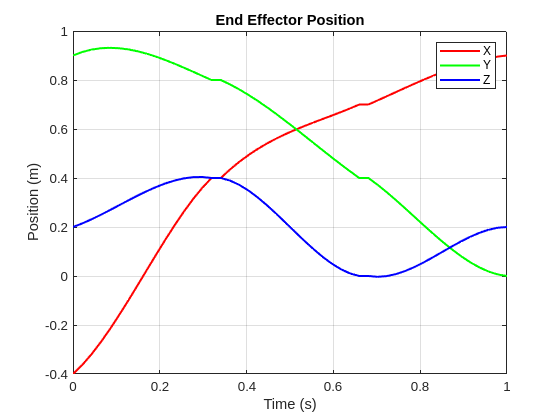

f1= figure;
plot(time, interpolatedPoints(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, interpolatedPoints(:,2), 'g', 'LineWidth', 1.5);
plot(time, interpolatedPoints(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Position');
xlabel('Time (s)');
ylabel('Position (m)');
legend({'X', 'Y', 'Z'});
grid on;

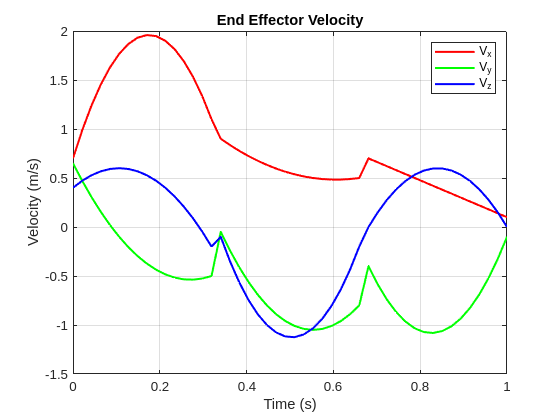

savefig(f1,"catmullp.fig");   % saves the figure  


% Velocity plot (showing X, Y, Z components)
f2= figure;
plot(time, velocities(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, velocities(:,2), 'g', 'LineWidth', 1.5);
plot(time, velocities(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Velocity');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend({'V_x', 'V_y', 'V_z'});
grid on;

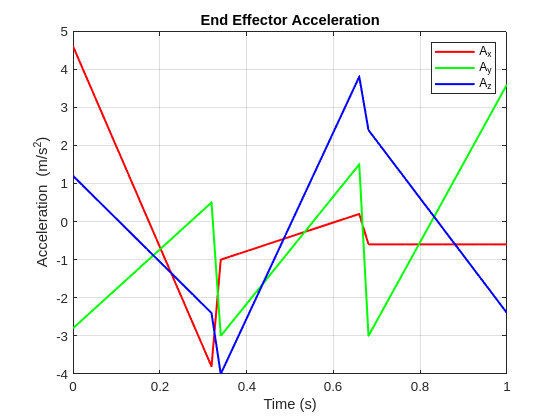

savefig(f2,"catmullv.fig");   % saves the figure  

% Acceleration plot (showing X, Y, Z components)
f3 = figure;
plot(time, accelerations(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, accelerations(:,2), 'g', 'LineWidth', 1.5);
plot(time, accelerations(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Acceleration');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend({'A_x', 'A_y', 'A_z'});
grid on;

savefig(f3,"catmulla.fig");   % saves the figure  


% % Visualize the robot's path and waypoints
% figure;
% show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
% hold on;
% 
% % Plot interpolated trajectory
% plot3(interpolatedPoints(:, 1), interpolatedPoints(:, 2), interpolatedPoints(:, 3), 'ro-', 'LineWidth', 2);
% 
% % Plot waypoints (control points)
% plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'bo-', 'MarkerFaceColor', 'b');
% 
% % Add labels
% text(waypoints(1,:), waypoints(2,:), waypoints(3,:), {'1','2','3','4','5','6'}, 'VerticalAlignment','top','HorizontalAlignment','left');
% 
% % Animate the robot motion along the path
% % for i = 1:size(interpolatedPoints, 1)
% %     % Compute IK for the interpolated position
% %     T = trvec2tform(interpolatedPoints(i, :));  % Convert to homogeneous transformation
% %     [theta, ~] = ik('tool0', T, weights, initialGuess);
% %     show(ur5e, theta, 'Frames', 'on', 'PreservePlot', false);
% %     pause(0.1); % Adjust for smooth animation
% % end
% grid on;
% axis equal;
% view(3);

% % Compute distances between consecutive interpolated points
% numPoints = size(interpolatedPoints, 1);
% distances = zeros(numPoints-1, 1); % Preallocate distance array
% 
% for i = 1:numPoints-1
%     % Compute Euclidean distance between consecutive points
%     distances(i) = norm(interpolatedPoints(i+1, :) - interpolatedPoints(i, :));
% end
% 
% % Compute pairwise distances
% distances = sqrt(sum(diff(interpolatedPoints).^2, 2));
% 
% % Plot distances
% figure;
% plot(1:length(distances), distances, 'LineWidth', 2);
% title('Pairwise Distances Between Interpolated Points');
% xlabel('Sample Point Index');
% ylabel('Distance (m)');
% grid on;
% 
% % Plot time distribution curve
% figure;
% plot(1:length(time),time, 'LineWidth', 2);
% title('Uniform Time Distribution');
% ylabel('Normalized Time');
% xlabel('Sample Point Index');
% grid on;
% 

% % Total time taken to complete task
% 
% % Compute pairwise distances between consecutive points
% distances = sqrt(sum(diff(interpolatedPoints).^2, 2)); % Size: (N-1) x 1
% % Compute velocity magnitudes at each interpolated point
% velocities_magnitude = sqrt(sum(velocities.^2, 2)); % Size: N x 1
% % Average velocities between consecutive points
% averageVelocities = (velocities_magnitude(1:end-1) + velocities_magnitude(2:end)) / 2;
% % Time taken for each segment
% timeSegments = distances ./ averageVelocities; % Size: (N-1) x 1
% % Total time to reach the last waypoint
% totalTime = sum(timeSegments);
% % Display total time
% fprintf('Total time to reach the last waypoint: %.2f seconds\n', totalTime);
% 
